%%Assignment-2
syms s

%System Parameters
m1 = 1e-3; %mass of the lens, m1, kg
m2 = 100e-3; %mass of the frame, m2, kg
x_dist = 200e-6; %amplitude of disturbance from fixed world to the frame, m
f_dist = 25; %natural frequency of the system that connects frame to the fixed world, Hz
w_dist = 2*pi*f_dist;%f_dist, rad/s
x_error = 0.2e-6; %amplitude of allowed error, m

%calculating stiffness between a)world and frame, and b)frame and lens
k2 = m2*(w_dist^2); %stiffness between world and the frame
k1 = (m1*(w_dist^2)*x_dist)/x_error; %stiffness between frame and lens

%adding damping for god's love
zeta = 0.05;
c1 = 2*zeta*sqrt(k1*m1);
c2 = 2*zeta*sqrt(k2*m2);

%equation #2 rearranged to solve for Kp
Kp = m1*(w_dist^2)*((x_dist/x_error)-1);

%equation #3 rearranged to solve for f_bw
f_bw = f_dist*sqrt((x_dist/x_error));

%calculating Td = 1/wd for derivative control
f_d = f_bw/3;
w_d = 2*pi*f_d;
T_d = 1/w_d;
%Calculating w_i
f_i = f_bw/10;
w_i = 2*pi*f_i;
T_i = 1/w_i;


s = tf('s');

%Initial PD_controller
PD_controller = Kp*(1+T_d*s);
%PID_controller = Kp*()

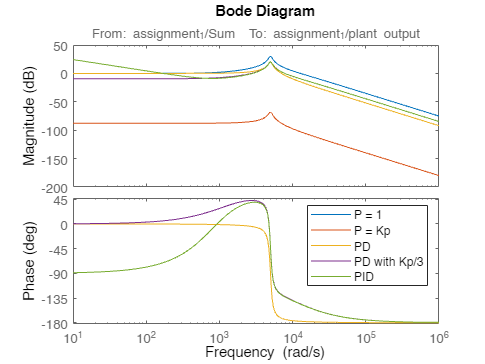


load("Assignment_2_linearizer.mat");

Linsys1 = LinearAnalysisToolProject.Plots(1).Variables.Value; % P = 0
Linsys2 = LinearAnalysisToolProject.Plots(2).Variables.Value; % P = Kp
Linsys3 = LinearAnalysisToolProject.Plots(3).Variables.Value; % PD
Linsys4 = LinearAnalysisToolProject.Plots(4).Variables.Value; % PD, with Kp/3
Linsys5 = LinearAnalysisToolProject.Plots(5).Variables.Value; % PID

%Plotting controllers all together
figure;
bode(Linsys1,Linsys2,Linsys3,Linsys4,Linsys5)
legend('P = 1','P = Kp','PD','PD with Kp/3','PID')

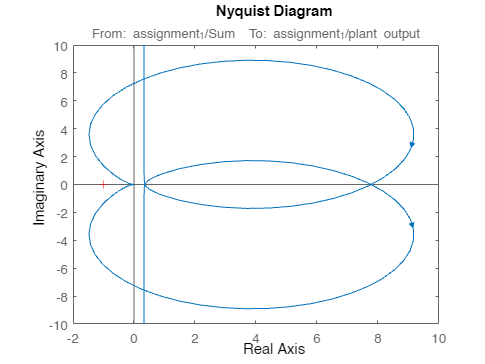


%Plotting nyquist plot
figure;
nyquist(Linsys5);

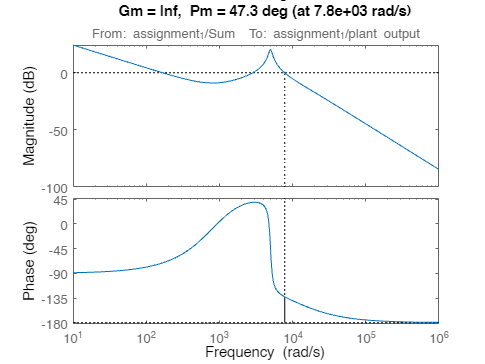

%Getting stability margins (GM & PM)
figure;
margin(Linsys5);


%%% Q13 - Q15 %%%%%

%Adding transport and limit on motor bandwidth
%Tdelay = 1e-6; %Delay
Tdelay = 10e-6; %Delay2 uncomment for Q15
f_mbw = 50e3; %Limited motor bandwitdth
%f_mbw = 3e3; %Limited motor bandwitdth 2 - Uncomment for Q14
%f_mbw = 750;
w_mbw = 2*pi*f_mbw;
T_mbw = 1/w_mbw;
PadeFilter = 1/(1+T_mbw*s)^2;


%Load linearizer for the system with transport delay and the filter
Linearize_2 = load("Assignment_2_linearizer_2.mat");
Linsys6 = Linearize_2.LinearAnalysisToolProject.Plots(1).Variables.Value; % Delay 1, bandwidth 50k
Linsys7 = Linearize_2.LinearAnalysisToolProject.Plots(2).Variables.Value; % Delay 1, bandwidth 3k
Linsys8 = Linearize_2.LinearAnalysisToolProject.Plots(2).Variables.Value; % Delay 10,bandwidth 50k
plant_15_ss = Linearize_2.LinearAnalysisToolProject.Plots(10).Variables.Value;

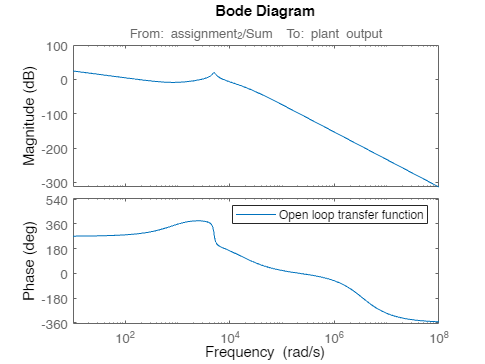

%%Q13
%Plotting the open loop transfer function
figure;
bode(Linsys6);
legend('Open loop transfer function')

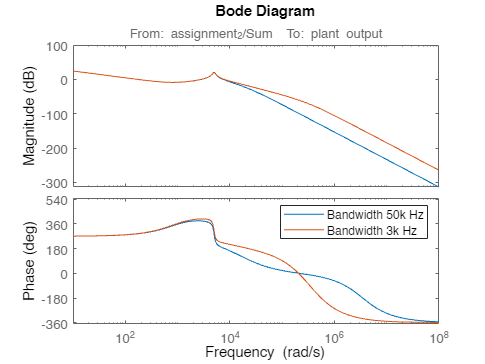

%%Q14
%Plotting the comparison
figure;
bode(Linsys6,Linsys7)
legend('Bandwidth 50k Hz','Bandwidth 3k Hz')


%Getting phase margin of the open loops
[Gm1,Pm1,Wcg1,Wcp1] = margin(Linsys6);
[Gm2,Pm2,Wcg2,Wcp2] = margin(Linsys7);
disp(Pm1)

    5.5771



disp(Pm2)

   40.0042



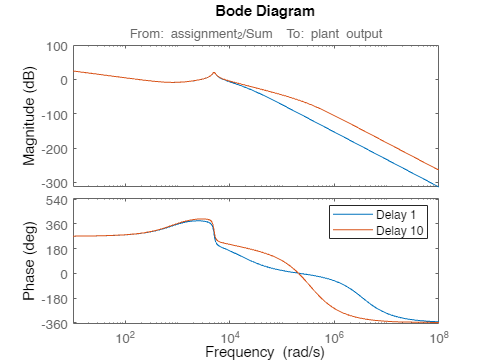


%Q15

%Plotting the comparison
figure;
bode(Linsys6,Linsys8)
legend('Delay 1','Delay 10')


%Getting phase margin of the open loop
[Gm3,Pm3,Wcg3,Wcp3] = margin(Linsys8);
disp(Pm1)

    5.5771



disp(Pm3)

   40.0042



plant_15 = tf(plant_15_ss);



load('controller_q15.mat');
controller_q15 = shapeit_data.C_tf;